clear all
clearvars
close all
clc
% read_Intan_RHS2000_file_og;
% [file, path, filterindex] = ...
%     uigetfile('*.rhs', 'Select an RHS2000 Data File', 'MultiSelect', 'off');

% LFP = BPF(amplifier_data, 25000, 1, 1000);%3 kilohertz,  1,800,069
% LFP_re = resample(LFP', 3000, 25000)';
% %nuovo_nome = "LFP_" + file + ".mat";
% %save(nuovo_nome, 'LFP_re'); %'-v7.3'

% ===============
% QUESTO CODICE PRENDE IN INPUT LOCAL FILED POTENTIAL
% ===============
clear all
clearvars
close all
clc
[file, pathname] = uigetfile('*.mat', 'Select MAT-file');
fullpath = fullfile(pathname, file);
data = load(fullpath);
LFP = data.LFP_re;

Fs = 3000; % Frequenza di campionamento
N_canali = size(LFP, 1); 

N_campioni = size(LFP, 2);

% Parametri della Finestra Scorrevole (da Gervasoni):
L_finestra = 2 * Fs; % lunga 2 secondi quindi 50000 campioni
L_passo = 1 * Fs; % centrate ogni 1 secondo quindi ogni 25000 campioni
N_finestre = floor((N_campioni - L_finestra) / L_passo) + 1; % numero di finestre temporali (punti di stato 2D finali)
% Pre-allocazione delle Matrici dei Rapporti (Tempo x Canali)
M_Ratio1 = zeros(N_finestre, N_canali); % Ratio 1: (0.5-20 Hz) / (0.5-55 Hz)
M_Ratio2 = zeros(N_finestre, N_canali); % Ratio 2: (0.5-4.5 Hz) / (0.5-9 Hz)

disp(['Numero di bin temporali (punti di stato): ', num2str(N_finestre)]);

Numero di bin temporali (punti di stato): 599


% --- Preparazione delle Frequenze ---
% Vettore delle frequenze (utile per identificare gli indici delle bande)
f_range = Fs * (0:(L_finestra/2)) / L_finestra;
% Funzione per trovare gli indici delle bande
get_band_indices = @(fLow, fHigh) (f_range >= fLow & f_range <= fHigh);

% --- Loop Principale (Tempo e Canali) ---
for t = 1:N_finestre % Loop sul tempo (Finestre)
    
    % Definisci la finestra temporale
    indice_start = (t - 1) * L_passo + 1;
    indice_end = indice_start + L_finestra - 1;
    finestra_dati = LFP(:, indice_start:indice_end);
    
    for c = 1:N_canali % Loop sui canali
        segnale = finestra_dati(c, :);
        
        % 1. Applicazione della Hanning Window per la regolarizzazione
        segnale_finestrato = segnale .* hann(L_finestra)'; %% la fa per non avere spectral leakage
        
        % 2. Calcolo della FFT e della Potenza Spettrale
        Y = fft(segnale_finestrato);
        Pyy = abs(Y / L_finestra).^2; % Potenza (Periodogramma)
        Pyy_half = Pyy(1:L_finestra/2 + 1); % Metà positiva dello spettro
        
        % --- Calcolo Ratio 1: (0.5-20 Hz) / (0.5-55 Hz) ---
        ind_num1 = get_band_indices(0.5, 20);
        ind_den1 = get_band_indices(0.5, 55);
        Power_Num1 = sum(Pyy_half(ind_num1));
        Power_Den1 = sum(Pyy_half(ind_den1));
        
        M_Ratio1(t, c) = Power_Num1 / Power_Den1;
        
        % --- Calcolo Ratio 2: (0.5-4.5 Hz) / (0.5-9 Hz) ---
        ind_num2 = get_band_indices(0.5, 4.5);
        ind_den2 = get_band_indices(0.5, 9);
        Power_Num2 = sum(Pyy_half(ind_num2));
        Power_Den2 = sum(Pyy_half(ind_den2));
        
        M_Ratio2(t, c) = Power_Num2 / Power_Den2;
    end
end

% =============
% PER RIPORTARE TUTTE LE MATRICI ALLA STESSA DIMENSIONE
% ==============
% TARGET_CHANNELS = 32;
% M_Ratio_Matrix = M_Ratio1;
% [~, og_channels] = size(M_Ratio_Matrix);
% if og_channels > TARGET_CHANNELS
%     [coeff, ~, ~] = pca(M_Ratio_Matrix);
%     num_pc_importanti = 5; % ma anche considerare solo le prime 2 PCA
%     loadings_rilevanti = coeff(:, 1:num_pc_importanti);
%     contributo_canali = sum(abs(loadings_rilevanti), 2);% per ogni riga somma tutti i valori
%     num_canali_da_scartare = og_channels - TARGET_CHANNELS; % 16 da scartare
%     [~, idx_ordinati] = sort(contributo_canali, 'ascend'); % Riga chiave: inizia dai più piccoli (da scartare) e finisce con i più grandi
%     indici_canali_da_mantenere = idx_ordinati(num_canali_da_scartare + 1 : end); % scarta i primi 16, che sono i più piccoli
%     indici_canali_da_mantenere = sort(indici_canali_da_mantenere);
%     M_Ratio_Matrix = M_Ratio_Matrix(:, indici_canali_da_mantenere);
%     M_Ratio1 = M_Ratio_Matrix;
% end
% M_Ratio_Matrix = M_Ratio2;
% [~, og_channels] = size(M_Ratio_Matrix);
% if og_channels > TARGET_CHANNELS
%     [coeff, ~, ~] = pca(M_Ratio_Matrix);
%     num_pc_importanti = 5; % ma anche considerare solo le prime 2 PCA
%     loadings_rilevanti = coeff(:, 1:num_pc_importanti);
%     contributo_canali = sum(abs(loadings_rilevanti), 2);% per ogni riga somma tutti i valori
%     num_canali_da_scartare = og_channels - TARGET_CHANNELS; % 16 da scartare
%     [~, idx_ordinati] = sort(contributo_canali, 'ascend'); % Riga chiave: inizia dai più piccoli (da scartare) e finisce con i più grandi
%     indici_canali_da_mantenere = idx_ordinati(num_canali_da_scartare + 1 : end); % scarta i primi 16, che sono i più piccoli
%     indici_canali_da_mantenere = sort(indici_canali_da_mantenere);
%     M_Ratio_Matrix = M_Ratio_Matrix(:, indici_canali_da_mantenere);
%     M_Ratio2 = M_Ratio_Matrix;
% end

% nome_matrice1 = "M_Ratio1_" + file + ".mat";
% save(nome_matrice1, 'M_Ratio1'); %'-v7.3'
% nome_matrice2 = "M_Ratio2_" + file + ".mat";
% save(nome_matrice2, 'M_Ratio2'); %'-v7.3'

% --- PCA: Riduzione dei Canali ---
% M_Ratio[1/2] è [Tempo x Canali]. La PCA riduce l'asse Canali.
[coeff1, score1, ~] = pca(M_Ratio1);
[coeff2, score2, ~] = pca(M_Ratio2);
%coeff: le colonne sono le Componenti Principali e le righe sono i contributi di ogni canale a ciascuna Componente Principale.

% I PC1 sono i due assi dello spazio degli stati 2D (non smussati)
PC1_prima = score1(:, 1); 
PC1_seconda = score2(:, 1); 

% --- Smoothing Hanning (Finestra di 20 secondi) ---
% La serie PC ha una risoluzione di 1 punto/secondo.
larghezza_filtro_punti = 20; 
hamming = hann(larghezza_filtro_punti, 'symmetric');

% Applicazione della convoluzione (smoothing)
PC1_nuovo = conv(PC1_prima, hamming, 'same');
PC2_nuovo = conv(PC1_seconda, hamming, 'same');

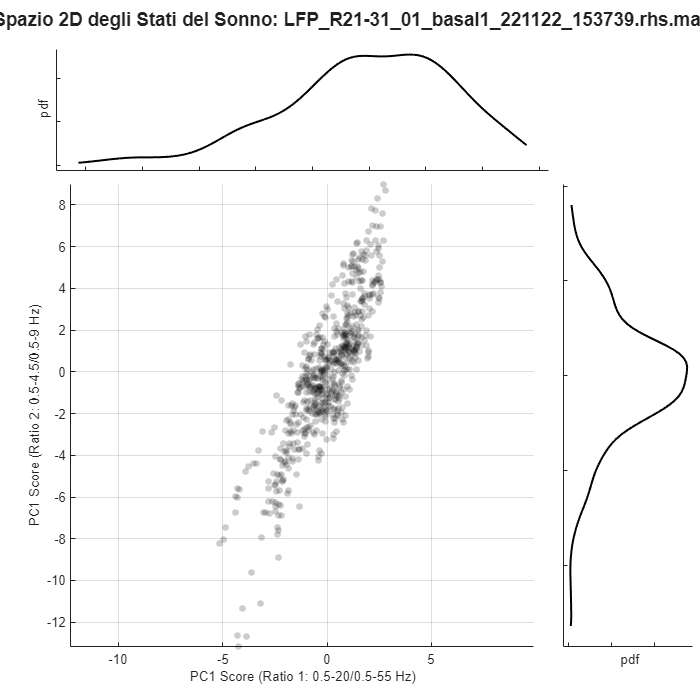

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1
Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1
Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


% --- PLOTTAGGIO dello Spazio 2D degli Stati ---
% close all
% figure
% scatter(PC1_nuovo, PC2_nuovo, 5, 'k', '.');
% xlabel('PC1 Score (Ratio 1: 0.5-20/0.5-55 Hz)');
% ylabel('PC1 Score (Ratio 2: 0.5-4.5/0.5-9 Hz)');
% title(file)
% grid on;
% axis equal;
% 1. Preparazione dei dati per Gramm
DatiGramm.PC1 = PC1_nuovo;
DatiGramm.PC2 = PC2_nuovo;

% Calcola i limiti simmetrici (per 'axis equal')
lims_x = [min(DatiGramm.PC1) max(DatiGramm.PC1)];
lims_y = [min(DatiGramm.PC2) max(DatiGramm.PC2)];
max_range = max([diff(lims_x), diff(lims_y)]) / 2;
center_x = mean(lims_x);
center_y = mean(lims_y);

x_lims_sym = [center_x - max_range, center_x + max_range];
y_lims_sym = [center_y - max_range, center_y + max_range];

% --- Inizializzazione della Figura e del Layout Multiplo ---
clear g
figure('Position',[100 100 700 700]);

% Parametri di Layout:
Plot_Width = 0.75; Density_Margin = 0.2; Margin_Gap = 0.01; Plot_Height = 0.75;

% -------------------------------------------------------------
% 1. Distribuzione Marginale X (In Alto)
g(1,1)=gramm('x',DatiGramm.PC1);
g(1,1).set_layout_options('Position',[0 0.8 0.8 0.2],... 
    'legend',false,... 
    'margin_height',[0.02 0.05],... 
    'margin_width',[0.1 0.02],...
    'redraw',false); 
g(1,1).set_names('x','');
g(1,1).set_color_options('map', [0 0 0]);
g(1,1).stat_density('function','pdf', 'extra_x', 0);
g(1,1).axe_property('XTickLabel','','YTickLabel','');


% -------------------------------------------------------------
% 2. Mappa degli Stati (Centro)
g(2,1)=gramm('x',DatiGramm.PC1,'y',DatiGramm.PC2);
g(2,1).set_names('x','PC1 Score (Ratio 1: 0.5-20/0.5-55 Hz)','y','PC1 Score (Ratio 2: 0.5-4.5/0.5-9 Hz)');
g(2,1).set_color_options('map', [0 0 0]);
g(2,1).geom_point('alpha', 0.2); 
g(2,1).set_point_options('markers',{'o'}); 
%g(2,1).stat_bin2d('nbins',[20 20], 'geom','contour');  

g(2,1).set_layout_options('Position',[0 0 0.8 0.8],...
    'legend',false,...
    'margin_height',[0.1 0.02],...
    'margin_width',[0.1 0.02],...
    'redraw',true);
% Forza Axis Equal e Limiti Simmetrici
g(2,1).axe_property('DataAspectRatio', [1 1 1]);
g(2,1).axe_property('XLim', x_lims_sym);
g(2,1).axe_property('YLim', y_lims_sym);
g(2,1).axe_property('Ygrid','on', 'XGrid','on'); 

% -------------------------------------------------------------
% 3. Distribuzione Marginale Y (A Destra)
g(3,1)=gramm('x',DatiGramm.PC2);
g(3,1).set_layout_options('Position',[0.8 0 0.2 0.8],...
    'legend_pos',[0.83 0.75 0.2 0.2],...
    'margin_height',[0.1 0.02],...
    'margin_width',[0.02 0.05],...
    'redraw',true);
g(3,1).set_names('x','');
g(3,1).set_color_options('map', [0 0 0]);
g(3,1).stat_density('function','pdf', 'extra_x', 0); 
g(3,1).coord_flip();
g(3,1).axe_property('XTickLabel','','YTickLabel','');

% -------------------------------------------------------------
% 4. Impostazioni Globali e Disegno
g.set_title(['Spazio 2D degli Stati del Sonno: ' file]);
g.draw();